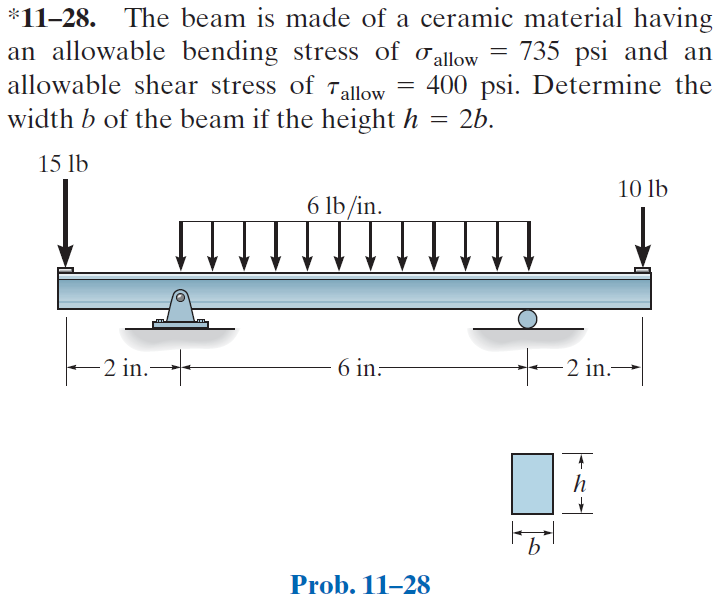

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-28P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-28P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

B_min = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('concentrated', 'force', -15*u.lbf, 0);
b = b.add('reaction', 'force', 'R1', 2*u.in, [false true]);
b = b.add('reaction', 'force', 'R2', 8*u.in);
b = b.add('concentrated', 'force', -10*u.lbf, 10*u.in);
b = b.add('distributed', 'force', -6*u.lbf/u.in, [2 8]*u.in);
b.L = 10*u.in;

# section properties

B = sym('B', 'positive');
H(B) = 2*B;
b.I = B*H^3/12;
A = B*H;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{3\,\left(x-2\,\mathrm{in}\right)\,\left(5\,x^{2}+10\,x\,\mathrm{in}-92\,{\mathrm{in}}^{2}\right)}{4\,B^{4}\,\text{E}}\,\mathrm{lbf} & \text{ if }x\leq 2\,\mathrm{in}\\ -\frac{\left(x-2\,\mathrm{in}\right)\,\left(x-8\,\mathrm{in}\right)\,\left(9\,x^{2}-100\,x\,\mathrm{in}+320\,{\mathrm{in}}^{2}\right)}{24\,B^{4}\,\text{E}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left(2\,\mathrm{in},8\,\mathrm{in}\right]\\ \frac{\left(x-8\,\mathrm{in}\right)\,\left(5\,x^{2}-110\,x\,\mathrm{in}+512\,{\mathrm{in}}^{2}\right)}{2\,B^{4}\,\text{E}}\,\mathrm{lbf} & \text{ if }8\,\mathrm{in}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{3\,\left(112\,{\mathrm{in}}^{2}-15\,x^{2}\right)}{4\,B^{4}\,\text{E}}\,\mathrm{lbf} & \text{ if }x\leq 2\,\mathrm{in}\\ -\frac{6\,x^{3}-95\,x^{2}\,\mathrm{in}+488\,x\,{\mathrm{in}}^{2}-800\,{\mathrm{in}}^{3}}{4\,B^{4}\,\text{E}}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left(2\,\mathrm{in},8\,\mathrm{in}\right]\\ \frac{3\,\left(5\,x^{2}-100\,x\,\mathrm{in}+464\,{\mathrm{in}}^{2}\right)}{2\,B^{4}\,\text{E}}\,\mathrm{lbf} & \text{ if }8\,\mathrm{in}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -15\,x\,\mathrm{lbf} & \text{ if }x<2\,\mathrm{in}\\ -\frac{9\,x^{2}-95\,x\,\mathrm{in}+244\,{\mathrm{in}}^{2}}{3}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left[2\,\mathrm{in},8\,\mathrm{in}\right]\\ 10\,\left(x-10\,\mathrm{in}\right)\,\mathrm{lbf} & \text{ if }8\,\mathrm{in}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -15\,\mathrm{lbf} & \text{ if }x<2\,\mathrm{in}\\ -\frac{18\,x-95\,\mathrm{in}}{3}\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left[2\,\mathrm{in},8\,\mathrm{in}\right]\\ 10\,\mathrm{lbf} & \text{ if }8\,\mathrm{in}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<2\,\mathrm{in}\\ -6\,\frac{\mathrm{lbf}}{\mathrm{in}} & \text{ if }x\in \left[2\,\mathrm{in},8\,\mathrm{in}\right]\\ 0 & \text{ if }8\,\mathrm{in}<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra, 4) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} R_{1} & 34.67\,\mathrm{lbf}\\ R_{2} & 26.33\,\mathrm{lbf} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

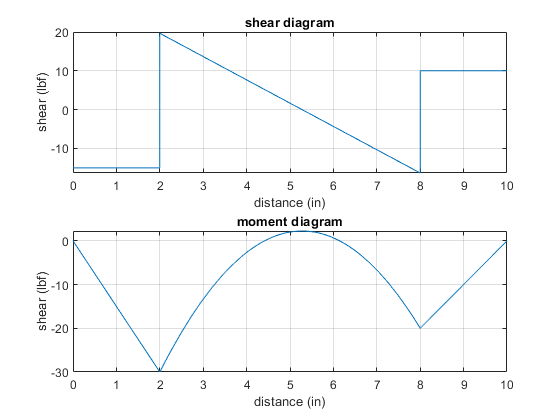

beam.shear_moment(m, v, [0 b.L], {'lbf', 'in'});

# maximum loads

M_max = -m(2*u.in)

$$M\_max = 30\,\mathrm{in}\,\mathrm{lbf}$$

V_max = v(2*u.in);
V_max_vpa = vpa(V_max, 4) %#ok<NASGU> 

$$V\_max\_vpa = 19.67\,\mathrm{lbf}$$

# maximum stresses

C = H/2;
sigma_max = rewrite(M_max*C/b.I, [u.psi u.in])

$$sigma\_max(B) = \frac{45}{B^{3}}\,{\mathrm{in}}^{3}\,\mathrm{psi}$$

tau_max = rewrite(3*V_max/(2*A), [u.psi u.in])

$$tau\_max(B) = \frac{59}{4\,B^{2}}\,{\mathrm{in}}^{2}\,\mathrm{psi}$$

# minimum beam width due to bending

sigma_allow = 735*u.psi;
B_min.bending = solve(sigma_max == sigma_allow);
B_min.bending = simplify(B_min.bending);
B_min_bending = vpa(B_min.bending, 2) %#ok<NASGU> 

$$B\_min\_bending = 0.39\,\mathrm{in}$$

# minimum beam width due to shear

tau_allow = 400*u.psi;
B_min.shear = solve(tau_max == tau_allow);
B_min.shear = simplify(B_min.shear);
B_min_shear = vpa(B_min.shear, 2) %#ok<NASGU> 

$$B\_min\_shear = 0.19\,\mathrm{in}$$

# limit beam width

B_min_vals = [B_min.bending B_min.shear];
loc = sigma_max(B_min_vals) <= sigma_allow & ...
      tau_max(B_min_vals) <= tau_allow;
B_min.limit = B_min_vals(isAlways(loc));
B_min_limit = vpa(B_min.limit, 2) %#ok<NASGU> 

$$B\_min\_limit = 0.39\,\mathrm{in}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear ra_vpa;
clear V_max_vpa;
clear B_min_bending
clear B_min_shear;
clear B_min_vals loc B_min_limit;